***Bureau d'étude Sous Marin***

clear all
close all
clc

# Introduction

Ce bureau d'étude à pour objectif d'étudier un système complexe multivariable, dans le cadre de la navigation d'un sous marin. Nous nous proposons de synthétiser des lois de contrôles insensibles et complètement découplées. Cette étude se fera sous Matlab, nous pourrons imposer la dynamique que nous souhaitons aux systèmes mais aussi créer un découplage du système et le rendre le moins sensible possible. Nous verrons aussi si nous pouvons obtenir simultanément découplage et insensibilité ou si un compromis doit être trouvé.

# **Partie I : Modélisation du système**

Dans cette première partie, nous allons modéliser le système à partir des données de l'énoncé. Nous pouvons modéliser le système sous forme d'équation d'état, de la forme : $\dot X = AX +BU \\
Y = CX +DU$ avec la matrice A, B, C et D composé des coefficients présentés plus bas. Nous posons la matrice $U = [pr \ po]$, comme étant la commande de notre système qui sont les angles soit de la proue, soit de la poupe. Notre sortie, $Y = [h \ \theta]$, h étant la profondeur du sous-marin et $\theta$ l'angle de tangente. 

%Les coefficients des matrices sont donc : 

% Define matrix values for 6 knots
a11_6 = -0.038006;
a12_6 = 0.89604;
a14_6 = 0.0014673;
a21_6 = 0.0017105;
a22_6 = -0.091676;
a24_6 = -0.0056095;
a34_6 = -3.0867;
b11_6 = -0.007542;
b12_6 = -0.022859;
b21_6 = 0.0017323;
b22_6 = -0.0022217;

% Define matrices A, B, C, and D for 6 knots
A_6knots = [a11_6, a12_6, 0, a14_6;
            a21_6, a22_6, 0, a24_6;
            1, 0, 0, a34_6;
            0, 1, 0, 0];

B_6knots = [b11_6, b12_6;
            b21_6, b22_6;
            0, 0;
            0, 0];

C_6knots = [0, 0, 1, 0;
            0, 0, 0, 1];

D_6knots = 0;

% Define matrix values for 30 knots
a11_30 = -0.19003;
a12_30 = 4.4802;
a14_30 = 0.0014673;
a21_30 = 0.0085526;
a22_30 = -0.45988;
a24_30 = -0.0056095;
a34_30 = -15.433;
b11_30 = -0.1855;
b12_30 = -0.57149;
b21_30 = 0.043308;
b22_30 = -0.055543;

% Define matrices A, B, C, and D for 30 knots
A_30knots = [a11_30, a12_30, 0, a14_30;
             a21_30, a22_30, 0, a24_30;
             1, 0, 0, a34_30;
             0, 1, 0, 0];

B_30knots = [b11_30, b12_30;
             b21_30, b22_30;
             0, 0;
             0, 0];

C_30knots = [0, 0, 1, 0;
             0, 0, 0, 1];

D_30knots = 0;


# **Partie II : Analyse des caractéristiques du système**

Pour l'analyse du système, nous considérons le cas 6knots puis le cas 30knots. Cette disjonction permettra une meilleure clarté des explications. 

- **Modèle du système sous forme d'espace d'état**

Nous écrivons le système sous forme d'équation d'état grâce à la fonction ss de matlab, qui prend en argument les matrices A, B, C et D et retourne le système d'équation.

sys_6knots = ss(A_6knots, B_6knots, C_6knots, D_6knots);
sys_30knots = ss(A_30knots, B_30knots, C_30knots, D_30knots);

[Vecp_6,Valp_6]=eig(A_6knots);
[Vecp_30,Valp_30]=eig(A_30knots);

Nous récuperons et stockons la valeur des valeurs et vecteurs propres pour les différents noeuds. 

## Etude pour 6 knots :

***        3. ******Observation des pôles :***

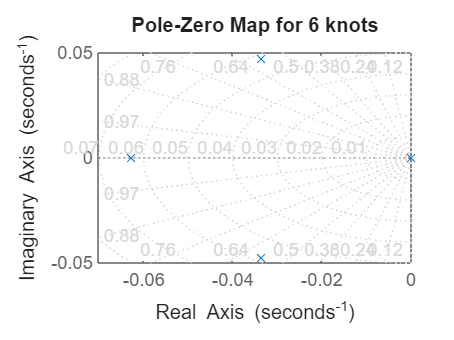

% Plot pole-zero maps for both systems
figure;
pzmap(sys_6knots);
title('Pole-Zero Map for 6 knots');
grid minor;

Nous remarquons que notre système présente 4 pôles distincts : 

p1 = 0

p2 = -3.35e-02 + 4.73e-02i

p3 = -3.35e-02 - 4.73e-02i

p4 = -6.27e-02

Nous remarquons que mis à part le pôle en 0, tous nos pôles sont à valeurs réelles strictement négative. Toutefois, ce pôle en 0 nous empêche de conclure. Nous somme donc en limite de stabilité. Après simulation, nous remarquons que notre système converge bel est bien, mais vers une valeur finie différente de 0.  Stabilité asymptotique pour l'angle. Le pôle en zéro n'influence pas la stabilité de l'angle.

Nous avons des pôles complexes conjugés dans le demi plan gauche, qui ont un faible coefficient d'amortissement. Ceci va entrainer un phénomène oscillatoire avant convergence.

***        2. ******Etude de l'observabilité et de la commandabilité:***

L'observabilité et la commandabilité du système s'étudie via l'analyse de l'espace image des matrices Qo et Gc. Nous allons donc nous intéresser au rang de ces 2 matrices. Nous Etudierons ces 2 propriétés pour les deux valeurs de vitesse (6 et 30 noeuds).

observabl_controlable(sys_6knots, A_6knots, 6);

Le rang de la matrice contrôlable pour 6 knots est : 4
Le rang de la matrice observable pour 6 knots est : 4
Le système pour 6 knots est observable et contrôlable.


stabilite_syst(A_6knots);

Nous ne pouvons pas déterminer la stabilité du système, car il possède 1 valeur(s) propre(s) nulle(s).
Le système possède 3 valeur(s) propre(s) négative(s).
                                                                        
         Pole              Damping       Frequency       Time Constant  
                                       (rad/TimeUnit)     (TimeUnit)    
                                                                        
  0.00e+00                -1.00e+00       0.00e+00               Inf    
 -3.35e-02 + 4.73e-02i     5.78e-01       5.80e-02          2.98e+01    
 -3.35e-02 - 4.73e-02i     5.78e-01       5.80e-02          2.98e+01    
 -6.27e-02                 1.00e+00       6.27e-02          1.60e+01    


Nous remarquons que les deux matrices sont bien de rang 4 tout comme l'espace de travail, nous pouvons donc conclure que le système pour 6 noeuds est bien observable et contrôlable.

***        4. ******Visualisation des réponses indicielles du système :***

Nous pouvons visualiser les réponses indicielles du système pour une entrée en échelon : 

% Convert to transfer function and plot
FBO_6 = tf(sys_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_6


FBO_6 =
 
  From input 1 to output...
          -0.007542 s^2 - 0.004486 s - 0.0002032
   1:  ---------------------------------------------
       s^4 + 0.1297 s^3 + 0.007561 s^2 + 0.0002107 s
 
                0.001732 s + 5.294e-05
   2:  -----------------------------------------
       s^3 + 0.1297 s^2 + 0.007561 s + 0.0002107
 
  From input 2 to output...
           -0.02286 s^2 + 0.002771 s + 0.0002498
   1:  ---------------------------------------------
       s^4 + 0.1297 s^3 + 0.007561 s^2 + 0.0002107 s
 
                -0.002222 s - 0.0001235
   2:  -----------------------------------------
       s^3 + 0.1297 s^2 + 0.007561 s + 0.0002107
 
Continuous-time transfer function.


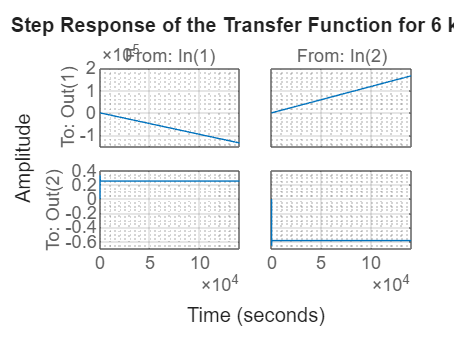

%% Alternatively, you can use step response
figure;
stepplot(FBO_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin a un comportement linéaire car nous appliquons une tension en échelon. Les deux courbes du bas montrent que l'angle du sous-marin est constant, car la position est linéaire

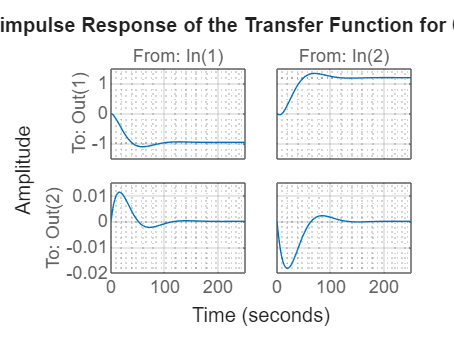

% Alternatively, you can use impulse response
figure;
impulse(FBO_6);
title('impulse Response of the Transfer Function for 6 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin suit un comportement en échelon, car nous appliquons une tension en impulsion. Les deux courbes du bas montrent que l'angle du sous-marin oscille au début, puis tend vers 0. Cela s'explique par le fait que, une fois que le sous-marin atteint son niveau de mer souhaité, il se remet à plat.

- ***Mise en avant d'un couplage***

Nous remarquons ici la présence naturelle d'un couplage entre nos grandeurs d'entrées et de sorties. Concrètement, ce couplage signifie qu'une consigne a une influence sur toutes les variables de sorties. 

Nous pouvons faire la même étude pour un système de 30 noeuds 

## Etude pour 30 knots :

- **Modèle du système sous forme d'espace d'état**

De la même manière que pour le système à 6 knots, nous pouvons écrire le système sous forme d'équation d'état.

***        2. ******Etude de l'observabilité et de la commandabilité:***

De la même façon, nous allons analyser la commandabilité ainsi que l'observabilité du système.

observabl_controlable(sys_30knots, A_30knots, 30);

Le rang de la matrice contrôlable pour 30 knots est : 4
Le rang de la matrice observable pour 30 knots est : 4
Le système pour 30 knots est observable et contrôlable.



fprintf('répondre la question 3\n');

répondre la question 3



stabilite_syst(A_30knots);

Nous ne pouvons pas déterminer la stabilité du système, car il possède 1 valeur(s) propre(s) nulle(s).
Le système possède 3 valeur(s) propre(s) négative(s).
                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
  0.00e+00    -1.00e+00       0.00e+00               Inf    
 -5.55e-01     1.00e+00       5.55e-01          1.80e+00    
 -6.67e-02     1.00e+00       6.67e-02          1.50e+01    
 -2.85e-02     1.00e+00       2.85e-02          3.51e+01    


Nous remarquons que le rang des matrices est de 4, ce qui correspond bien à l'espace image des matrices d'observabilité et de commandabilité, le système est donc contrôlable et observable.

***        3. ******Observation des pôles :***

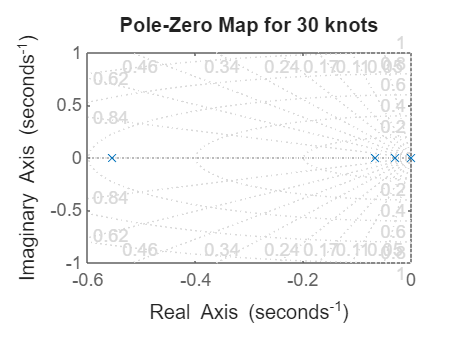

% Plot pole-zero maps for both systems
figure;
pzmap(sys_30knots);
title('Pole-Zero Map for 30 knots');
grid minor;

Nous pouvons voir que cette fois ci, nous avons 4 pôles réels : 

p1 = 0

p2 = -5.55e-01

p2 = -6.67e-02

p3 = -2.85e-02

Comme tout à l'heure nous ne pouvons conclure sur la stabilité du système. Celui ci est en limite de stabilité. A l'inverse, pour 30 noeuds, nous n'observerons pas d'oscillations du système avant de converger.

***        4. ******Visualisation des réponses indicielles du système :***

% Convert to transfer function and plot
FBO_30 = tf(sys_30knots);
fprintf('La fonction de transfert du système 30 knots:\n');

La fonction de transfert du système 30 knots:


FBO_30


FBO_30 =
 
  From input 1 to output...
             -0.1855 s^2 - 0.5597 s - 0.1035
   1:  -------------------------------------------
       s^4 + 0.6499 s^3 + 0.05468 s^2 + 0.001053 s
 
                0.04331 s + 0.006643
   2:  ---------------------------------------
       s^3 + 0.6499 s^2 + 0.05468 s + 0.001053
 
  From input 2 to output...
             -0.5715 s^2 + 0.3455 s + 0.235
   1:  -------------------------------------------
       s^4 + 0.6499 s^3 + 0.05468 s^2 + 0.001053 s
 
                -0.05554 s - 0.01544
   2:  ---------------------------------------
       s^3 + 0.6499 s^2 + 0.05468 s + 0.001053
 
Continuous-time transfer function.


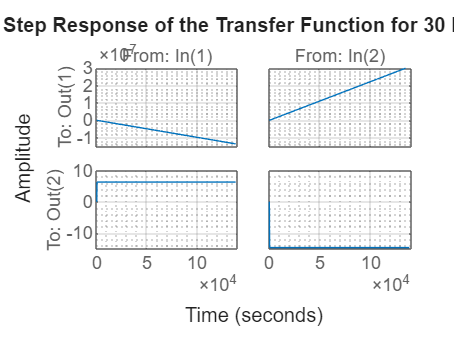


% Alternatively, you can use step response
figure;
stepplot(FBO_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin a un comportement linéaire car nous appliquons une tension en échelon. Les deux courbes du bas montrent que l'angle du sous-marin est constant, car la position est linéaire

fprintf('répondre la question 5\n');

répondre la question 5


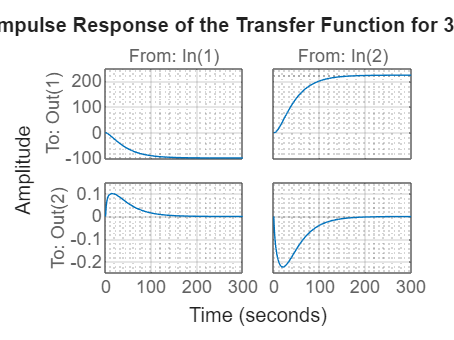

% Alternatively, you can use step response
figure;
impulse(FBO_30);
title('impulse Response of the Transfer Function for 30 knots');
grid minor;

Nous observons :

Les deux courbes du haut montrent que la position du sous-marin suit un comportement en échelon, car nous appliquons une tension en impulsion. Les deux courbes du bas montrent que l'angle du sous-marin oscille au début, puis tend vers 0. Cela s'explique par le fait que, une fois que le sous-marin atteint son niveau de mer souhaité, il se remet à plat.

# **Partie IV : Réalisation des objectifs**

- **Justification des valeurs propres**

Notre fonction de transfert est un ordre 4 (deux ordre 2). Il est donc possible sous certaines conditions, d'approximer cet ordre 4 par deux fonctions de transfert d'ordre 1. Donc pour chaque ordre 2, il est nécessaire de négliger la dynamique d'un pôle. L'autre pôle, est obtenue avec la relation classique : tr = 3tau.  

M=1;
lambda1=-3/100;
lambda2=-3/80;
Lambda=[lambda1, lambda1*10, lambda2, lambda2*10 ];
V=[0, 0, 1 ,2 ; 1, 2, 0, 0];

# **Partie V : Choix de la dynamique et découplage**

Dans cette partie, nous allons nous intéresser à la méthode permettant d'imposer une dynamique souhaitée ainsi que d'établir un découplage entre variables d'états et consignes.

- **Dimension et forme de la matrice de découplage**

Nous cherchons à découpler l'influence des entrées avec les variables d'états. Pour cela, nous imposons :

C.V = [0, 0 , * , * ; * , * , 0 , 0 ];

Ce qui permet d'imposer un découplage entre les grandeurs d'entrées et de sorties, dans la mesure où la consigne $y_{c1}$ ne peut agir que sur deux modes et idem pour $y_{c2}$. Nous pouvons donc déterminer la matrice V, assurant les conditions données pour CV.

V = [ * , * , * , * ;  * , * , * , * ;  * , * , 0 , 0 ; 0 , 0 , * , * ];

## Etude pour 6 knots :

**        2. ****Dynamique en boucle fermé**

L'objectif de cette partie est de déterminer la valeur de K permettant d'imposer une dynamique souhaitée pour le système en placant les pôles de manière désirées. 

Les étapes à suivre afin de pouvoir déterminer K, il nous faut : 

- Définir les matrices $M(\lambda_i)$ et $N(\lambda_i)$, tel que :    $M(\lambda_i) = I_n$ et $N(\lambda_i) = -(\lambda_iI_n - A)^{-1}B.M(\lambda_i)$

- Calculer la matrice $Z_i = N(\lambda_i)^{-1}. V_i$ , à partir de la matrice des vecteurs propres liées à $\lambda_i$

- Calculer la matrice $W_i = M(\lambda_i).Z_i$

- La matrice des gains K est obtenue par : $K = [w_1...w_n][v_1...v_n] ^{T} $

Nous pouvons donc implémenter ces équations sur MATLAB, et nous obtenons : 

Calcul de la dynamique en boucle fermé :

%% 6knots
[Vresult_6,K_6,H_6] = calcul_K_H(A_6knots, B_6knots, C_6knots, M,V, Lambda);

H_cor_6=Hcorriger(H_6,-1.8,0.27);

A_cor_6knots=A_6knots-B_6knots*K_6;
B_cor_6knots=B_6knots*H_cor_6;
C_cor_6knots=C_6knots;
D_cor_6knots=D_6knots;

sys_cor_6knots = ss(A_cor_6knots, B_cor_6knots, C_cor_6knots, D_cor_6knots);


La détermination de la forme de la matrice V, emmène maintenant aux choix des valeurs pour les coefficients *. Pour cela, plusieurs choix sont possibles : 

    - Soit le choix des valeurs pour * sont pris arbitrairement pour V en respectant la condition que V doit être inversible (car nécessité de calculer $V^{-1}$).

    - Optimiser le choix des vecteurs propres à partir des colonnes non entierement spécifiées.

Nous avons choisi cette deuxième option. Nous avons calculé la matrice V, en complétant chaque colonne à partir des équations $V_i = N(\lambda_i).z_i$

Le calcul de la matrice V est réalisé dans la fonction "calcul_K_H.m"

**        3. ****Détermination de la matrice H**

Nous souhaitons déterminer la forme de la matrice H qui permet un découplage à gauche de notre système. Pour ce faire, nous partons de la dimension de cette matrice. Pour respecter les contraines de dimension, cette matrice doit être de dimension 2x2. Nous posons alors :

H = [h11, h12; h21, h22];

Nous savons également que pour des contraintes de découplage, la matrice U.B.H doit être de la forme : [0 , * ; 0 , * ; * , 0; * , 0]. Ceci assure un découplage des variables de sorties avec les deuc consignes.

En posant la matrice UB(i,j), nous pouvons définir le système d'équation suivant : 


$$h_1 = 1$$



$$h_3 = \frac{-UB(1,1)}{UB(1,2)}.h_1$$



$$h_2 = 1$$



$$h_4 = \frac{-UB(4,1)}{UB(4,2)}.h_2$$


Le calcul de H comme de V se trouve dans la fonction "calcul_K_H.m", qui est joint avec le dossier du projet.

Enfin, il a été possible également de déterminer la valeur du gain statique à appliquer afin d'avoir un gain unitaire en régime permanent. Cette valeur de gain a directement été implémenté dans la fonction "Hcorriger.m".

Sachant ceci, nous pouvons observer dans le plan complexe la position des pôles.

stabilite_syst(A_cor_6knots);

Le système est stable et toutes les valeurs propres sont négatives.
                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
 -3.75e-01     1.00e+00       3.75e-01          2.67e+00    
 -3.75e-02     1.00e+00       3.75e-02          2.67e+01    
 -3.00e-01     1.00e+00       3.00e-01          3.33e+00    
 -3.00e-02     1.00e+00       3.00e-02          3.33e+01    


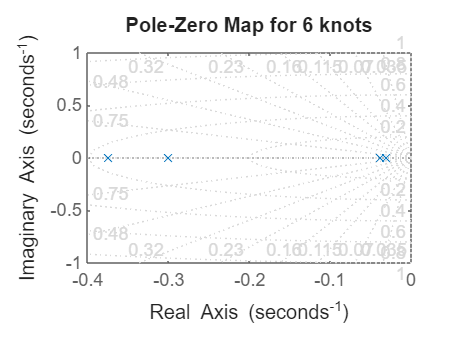

figure;
pzmap(sys_cor_6knots);
title('Pole-Zero Map for 6 knots');
grid minor;


% Convert to transfer function and plot
FBO_cor_6 = tf(sys_cor_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_cor_6


FBO_cor_6 =
 
  From input 1 to output...
                0.01409 s^2 + 0.00465 s + 0.0001268
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              -2.168e-19 s^2 - 1.204e-19 s - 1.952e-21
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
              1.298e-16 s^2 + 1.386e-17 s + 1.834e-18
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
               0.009131 s^2 + 0.003766 s + 0.0001284
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


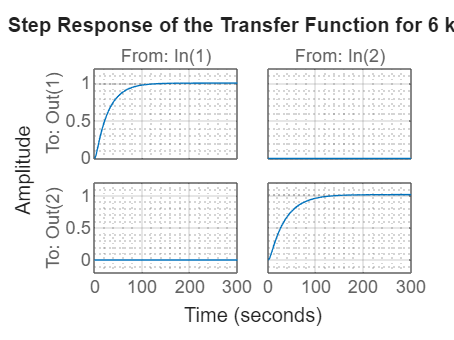


%% Alternatively, you can use step response
figure;
stepplot(FBO_cor_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

Nous remarquons que nos pôles sont correctements placés (cf valeur de l'énoncé). Nous obtenons donc 4 pôles réels strictement négatifs, donc le système est stable et sans oscillation avant de converger. En plus de ceci, nous remarquons un découplage entre grandeur d'entrées et de sorties qui se visualise grâce aux courbes en bas à gauche et en haut à droite qui sont constantes égale à 0.

## Etude pour 30 knots :

Nous pouvons raisonner de manière similaire pour un système de 30 noeuds :

%% 30knots
[Vresult_30,K_30,H_30] = calcul_K_H(A_30knots, B_30knots, C_30knots, M,V, Lambda);
H_cor_30=Hcorriger(H_30,-45,6.8);

A_cor_30knots=A_30knots-B_30knots*K_30;
B_cor_30knots=B_30knots*H_cor_30;
C_cor_30knots=C_30knots;
D_cor_30knots=D_30knots;

sys_cor_30knots = ss(A_cor_30knots, B_cor_30knots, C_cor_30knots, D_cor_30knots);


stabilite_syst(A_cor_30knots);

Le système est stable et toutes les valeurs propres sont négatives.
                                                            
   Pole        Damping       Frequency       Time Constant  
                           (rad/TimeUnit)     (TimeUnit)    
                                                            
 -3.75e-01     1.00e+00       3.75e-01          2.67e+00    
 -3.75e-02     1.00e+00       3.75e-02          2.67e+01    
 -3.00e-02     1.00e+00       3.00e-02          3.33e+01    
 -3.00e-01     1.00e+00       3.00e-01          3.33e+00    


figure;
pzmap(sys_cor_30knots);
title('Pole-Zero Map for 6 knots');
grid minor;

% Convert to transfer function and plot
FBO_cor_30 = tf(sys_cor_30knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_cor_30


FBO_cor_30 =
 
  From input 1 to output...
                0.01402 s^2 + 0.004628 s + 0.0001262
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              5.459e-16 s^2 + 2.211e-16 s + 6.142e-18
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
              -1.907e-10 s^2 - 1.287e-10 s - 2.145e-11
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                0.00902 s^2 + 0.003721 s + 0.0001268
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


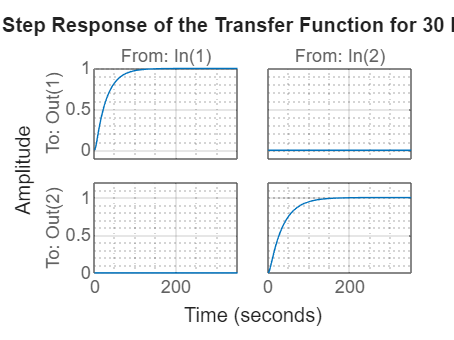


%% Alternatively, you can use step response
figure;
stepplot(FBO_cor_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

Comme pour l'autre partie, nous pouvons remarquer les pôles sont correctement placés (comme nous souhaitions). En plus de cette dynamique, nous pouvons également remarquer que le découplage a correctement fonctionné (une entrée ne commande qu'une seule sortie.

# **Partie VI : Découplage en mode statique**

L'objectif de cette partie est de déterminer la valeur de.

- **Preuve de l'équation Yc= CX**

Dans cette question, nous allons justifier que le découplage en statique peut être obtenu en posant comme matrice H, celle donnée par le sujet. 

Comme nous savons que $\Omega \;$= [$\Omega_{11}$, $\Omega_{12}$; $\Omega_{21}$, $\Omega_{22}$]= $[A, B; C,D]^{-1}$, d'où en multipliant par la matrice de droite de chaque côté, il vient, les 4 equations suivantes :

A*$\Omega_{11}$+ B*$\Omega_{12}$ = $I_{2}$

A*$\Omega_{12}$+ B*$\Omega_{22}$= $O_{2}$

C*$\Omega_{11}$ = $O_{2}$

C*$\Omega_{12}$ = $I_{2}$

D'où en écrivant l'expression de yc en remplançant H par sa valeur donné par l'énoncé, il vient : (K- $B^{-1}$*A)$\Omega_{12}$*$y_{c}$ = (- $B^{-1}$*A+K)$*$x, d'où 

yc = $\Omega_{12}^{-1}$x. D'où C = $\Omega_{12}^{-1}$.

        2. **Réponses indicielles de **$\delta h_{c}$** et **$\delta \theta_{c}$

   Nous allons maintenant simuler la réponse indicielle d'un échelon pour $\delta h_{c}$ et $\delta \theta_{c}$

%% 6knots
H_st_6=Hstatic(A_6knots,B_6knots,C_6knots,K_6);
B_st_6knots=B_6knots*H_st_6;

sys_st_6knots = ss(A_cor_6knots, B_st_6knots, C_cor_6knots, D_cor_6knots);

%% 30knots
H_st_30=Hstatic(A_30knots,B_30knots,C_30knots,K_30);
B_st_30knots=B_30knots*H_st_30;
sys_st_30knots = ss(A_cor_30knots, B_st_30knots, C_cor_30knots, D_cor_30knots);


        ***Etude du système pour 6 knots***

% Convert to transfer function and plot
FBO_st_6 = tf(sys_st_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_st_6


FBO_st_6 =
 
  From input 1 to output...
                0.01406 s^2 + 0.004641 s + 0.0001266
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                      -4.879e-20 s - 3.591e-36
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
               3.837e-16 s^2 + 1.22e-16 s + 3.629e-18
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003713 s + 0.0001266
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


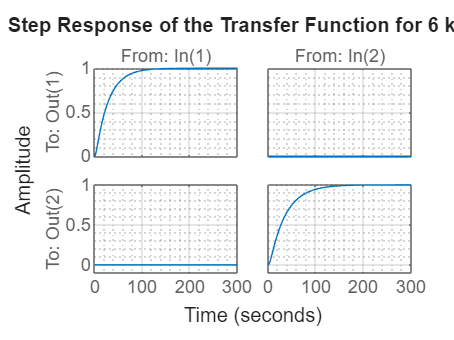


%% Alternatively, you can use step response
figure;
stepplot(FBO_st_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

        ***Etude du système pour 30 knots***

% Convert to transfer function and plot
FBO_st_30 = tf(sys_st_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_st_30


FBO_st_30 =
 
  From input 1 to output...
                0.01406 s^2 + 0.004641 s + 0.0001266
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              1.093e-16 s^2 + 4.098e-17 s - 1.342e-21
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
              2.188e-09 s^2 + 6.564e-10 s + 1.876e-17
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003713 s + 0.0001266
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


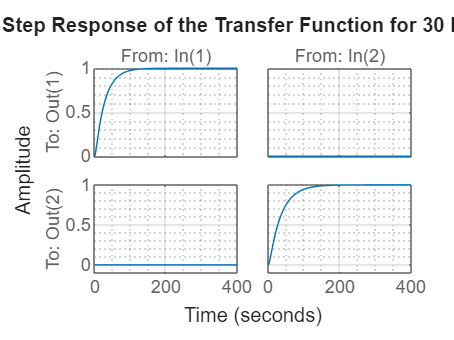


%% Alternatively, you can use step response
figure;
stepplot(FBO_st_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

Nous remarquons qu'en implémentant cette matrice H, notre système (6 knots ou 30knots) est bien découplé en mode statique. Autrement dit, le découplage a été étendu au cas statique.

***        3. ******Découplage satisfait du système***

Enfin dans cette dernière sous partie, nous allons vérifier que le découplage est correctement réalisé. Nous remarquons que le système est correctement découplé dans la mesure ou la consigne yc2 n'infleunce plus le comportement de la 1ère variable d'état, et inversement.

# **Partie VII : Placement pôle insensible**

- **Etude de la fonction place.m**

Pour ce faire, nous allons utiliser la fonction place, qui permet de placer les pôles en boucle fermé via un retour d'état. Pour ce faire, la fonction va calculer une matrice K, de telles manière que la matrice A-B*K possède les mêmes valeurs propres que celles souhaitées pour imposer la dynamique.

        2. **Implémentation du retour d'état **

Nous allons mettre en place la méthode de placement de pôle tout en minimisant la sensibilité du système. Nous allons donc utiliser la fonction place, qui en plus de calculer la velur de K permet de minimiser la sensibilité des pôles.


%% 6knots
K_place_6=place(A_6knots,B_6knots,Lambda);

A_place_6knots=A_6knots-B_6knots*K_place_6;


sys_place_6knots = ss(A_place_6knots, B_st_6knots, C_cor_6knots, D_cor_6knots);


%% 30knots
K_place_30=place(A_30knots,B_30knots,Lambda);

A_place_30knots=A_30knots-B_30knots*K_place_30;

sys_place_30knots = ss(A_place_30knots, B_st_30knots, C_cor_30knots, D_cor_30knots);


        ***Etude du système pour 6 knots***

Nous pouvons tracer la réponse indicielle pour un entrée en échelon :

% Convert to transfer function and plot
FBO_place_6 = tf(sys_place_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


FBO_place_6


FBO_place_6 =
 
  From input 1 to output...
                0.01406 s^2 + 0.004784 s + 0.0001311
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                      -0.0001725 s - 7.086e-06
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
                      -0.0004979 s - 1.736e-05
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003621 s + 0.0001231
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


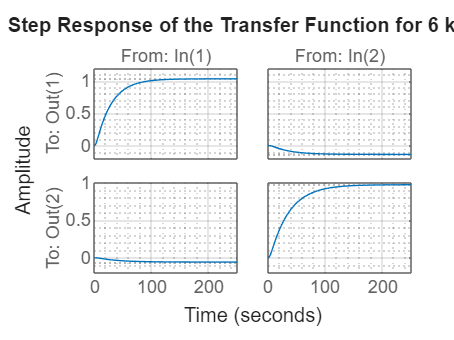

%% Alternatively, you can use step response
figure;
stepplot(FBO_place_6);
title('Step Response of the Transfer Function for 6 knots');
grid minor;

Nous remarquons cette fois ci que le découplage entre entrées et sorties ne semble s'être dégradé lors du placement de pôle avec comme exigence de minimiser la sensibilité. Nous analyserons ce phénomène dans la partie juste après.

        ***Etude du système pour 30 knots***


% Convert to transfer function and plot
FBO_place_30 = tf(sys_place_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_place_30


FBO_place_30 =
 
  From input 1 to output...
                0.01406 s^2 + 0.00485 s + 0.0001331
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
              1.093e-16 s^2 - 3.903e-05 s - 1.616e-06
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
  From input 2 to output...
               2.188e-09 s^2 - 0.002982 s - 0.0001041
   1:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
                 0.009 s^2 + 0.003579 s + 0.0001216
   2:  ------------------------------------------------------
       s^4 + 0.7425 s^3 + 0.1592 s^2 + 0.008353 s + 0.0001266
 
Continuous-time transfer function.


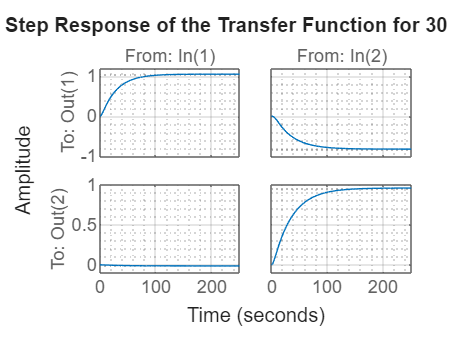

%% Alternatively, you can use step response
figure;
stepplot(FBO_place_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

Idem pour le système à 30 knots, nous remarquons que le découplage ne semble plus être aussi parfait, nous justifierons ce phénomène dans la secftion suivante.

        3. **Contraintes de découplage**

On remarque que nos systèmes présentent des phénomènes de couplage, $y_{c2}$ a une aussi une influence sur la dynamique de la 1ère variable d'état. Ceci est tout à fait normal, dans la mesure ou notre étude a été mené sur l'insensibilité des pôles et non sur le découplage. Il y a un compromis à trouver entre insensibilité et découplage. Nous devons faire un choix entre insensibilité et découplage dans nos lois de commande, c'est inéluctable.

Toutefois, Comme nous utilisons la matrice H dans le système, nous remarquons bien un decouplge dans le graphe en bas a gauche.

# **Parti VIII : Etude de sensibilité**

Dans cette partie nous allons regarder la sensibilité de notre système vis à vis de nos modes.

- **Etude de la fonction cond.m**

La fonction cond.m est utilisée pour calculer le nombre de conditionnement d'une matrice. Ce nombre permet de donner une information quantitative sur la sensibilité d'une matrice. 

Ce calcul se fait à travèrs le rapport de la valeur maximale singulière de la matrice divisée par la valeur minimale. 

        2.  **Etude des la sensibilité pour le placement de pôles choisi**

Nous allons maintenant étudier la sensibilité pour les pôles placés dans les parties précédentes du BE. 

Pour cela, nous allons récupérer les matrices des vecteurs propres car ce sont les matrices que nous inversons. Nous allons considérer les deux cas possibles (pour 6 et 30 noeuds).

[Vecp_cor_6, Valp_cor_6]=eig(A_cor_6knots);

[Vecp_cor_30, Valp_cor_30]=eig(A_cor_30knots);

[Vecp_place_6, Valp_place_6]=eig(A_place_6knots);

[Vecp_place_30, Valp_place_30]=eig(A_place_30knots);



## Etude pour 6 knots :

*Sensibilité de la boucle ouvert *

disp("insensibilité boucle ouverte :")

insensibilité boucle ouverte :


cond(Vecp_6)

ans = 1.5307e+03

*Sensibilité de la boucle fermé *

disp("insensibilité boucle fermée :")

insensibilité boucle fermée :


cond(Vecp_cor_6)

ans = 27.1246

*Sensibilité de la boucle mode placement de pole*

disp("insensibilité boucle fermé par placement de pôles :")

insensibilité boucle fermé par placement de pôles :


cond(Vecp_place_6)

ans = 28.1878

Nous remarquons que le passage de la boucle ouverte à la boucle fermé améliore le critère d'insensibilité. Pour ce qui est du placement de pôles, comme nous contraignons le système à adopter une dynamique souhaitée, ceux ci à comme influence de légèrement dégrader la sensibilité, en rendant le système plus sensible. 

*Sensibilité de la boucle inhibation d'une entrée de commande*

Nous pouvons maintenant étudier ce qui se passe lorsque nous inhibons une commande (U1 =0, puis U2 =0).

- Considérons le cas U1 = 0

Considérons que la première entrée U1 est nulle et U2 non nulle, nous calculons la valeur de la matrice de gain K nous permettant de placer les pôles souhaités. 

Une fois cette matrice déterminée, nous pouvons calculer les nouvelles valeurs des matrices A et B du modèle de la boucle fermée. En déterminant la matrice de vecteur propre de cette nouvelle matrice A corrigée, nous pouvons calculer l'insensibilité du système.


%% 6knots
K_U2_6= place(A_6knots,B_6knots,Lambda);

B_6knots_ter= B_6knots ;
B_6knots_ter(:,1) = 0;

A_U2_6knots=A_6knots-B_6knots_ter*K_U2_6;

B_st_6knots=B_6knots_ter*H_st_6;

%B_st_6knots_U2 = B_st_6knots;

%B_st_6knots_U2(:,2) = 0;

%sys_U2_6knots = ss(A_U2_6knots, B_st_6knots_U2, C_cor_6knots, D_cor_6knots);
sys_U2_6knots = ss(A_U2_6knots, B_st_6knots, C_cor_6knots, D_cor_6knots);

Nous pouvons donc visualiser la sensibilité du système (matrice des vecteurs propres), lorsque l'entrée U1 est nulle :

disp("insensibilité boucle fermé pour U1=0 :")

insensibilité boucle fermé pour U1=0 :



[Vecp_U2_6knots, Vp_U2_6knots] = eig(A_U2_6knots);
cond(Vecp_U2_6knots)

ans = 56.3452

- Réponse indicielle à un échelon pour U1=0

Nous pouvons maintenant visualiser la sortie à une consigne en échelon, afin de visualiser le comportement du système.

% Convert to transfer function and plot
FBO_U2_6 = tf(sys_U2_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


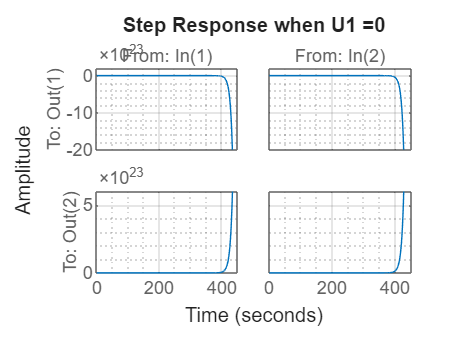

%FBO_U2_6
%% Alternatively, you can use step response
figure;
stepplot(FBO_U2_6);
title('Step Response when U1 =0');
grid minor;

Nous constatons que la sortie du système est presque nulle, en raison du découplage entre les entrées et les sorties. Cependant, elle n'est pas totalement nulle, car le système a été réglé pour être insensible. Cette insensibilité perturbe en partie le caractère découplant du système.

- U2=0

Nous pouvons raisonner de la même manière que lorsque l'entrée 1 était éteinte,

% K_U1_6= place(A_6knots,B_6knots,Lambda);
% 
% A_U1_6knots=A_6knots-B_6knots*K_U1_6;
% 
% B_st_6knots_U1 = B_st_6knots;
% 
% B_st_6knots_U1(:,1) = 0;
% 
% sys_U1_6knots = ss(A_U1_6knots, B_st_6knots_U1, C_cor_6knots, D_cor_6knots);


%% 6knots
K_U1_6= place(A_6knots,B_6knots,Lambda);

B_6knots_ter2= B_6knots ;
B_6knots_ter2(:,2) = 0;

A_U1_6knots=A_6knots-B_6knots_ter2*K_U1_6;

B_st_6knots=B_6knots_ter2*H_st_6;

%B_st_6knots_U2 = B_st_6knots;

%B_st_6knots_U2(:,2) = 0;

%sys_U2_6knots = ss(A_U2_6knots, B_st_6knots_U2, C_cor_6knots, D_cor_6knots);
sys_U1_6knots = ss(A_U1_6knots, B_st_6knots, C_cor_6knots, D_cor_6knots);

Nous pouvons donc visualiser la sensibilité du système (matrice des vecteurs propres), lorsque l'entrée U2 est nulle :

disp("insensibilité boucle fermé pour U2=0 :")

insensibilité boucle fermé pour U2=0 :



[Vecp_U1_6knots, Vp_U1_6knots] = eig(A_U1_6knots);
cond(Vecp_U1_6knots)

ans = 523.7372

Nous remarquons que...

- Réponse indicielle à un échelon pour U2=0

Nous pouvons maintenant visualiser la sortie à une consigne en échelon, afin de visualiser le comportement du système.


% Convert to transfer function and plot
FBO_U1_6 = tf(sys_U1_6knots);
fprintf('La fonction de transfert du système 6 knots :\n');

La fonction de transfert du système 6 knots :


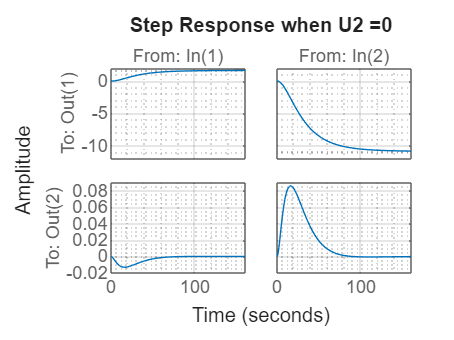

%FBO_U1_6
%% Alternatively, you can use step response
figure;
stepplot(FBO_U1_6);
title('Step Response when U2 =0');
grid minor;

Nous pouvons émettre une conclusion similaire du cas précédent au cas où U2 =0. 

## Etude pour 30 knots :

Nous avons également étudié le cas à 30 noeuds.

*Sensibilité de la boucle ouvert *

Pour 30knots

cond(Vecp_30)

ans = 1.1336e+04

*Sensibilité de la boucle fermé *

Pour 30knots

cond(Vecp_cor_30)

ans = 129.9299

*Sensibilité de la boucle mode placement de pole*

Pour 30knots

cond(Vecp_place_30)

ans = 136.0546

- On considère U1=0

%% 30knots
% K_U2_30=place(A_30knots,B_30knots(:,2),Lambda);
% 
% A_U2_30knots=A_30knots-B_30knots(:,2)*K_U2_30;
% 
% sys_U2_30knots = ss(A_U2_30knots, B_st_30knots(:,2), C_cor_30knots(2,:), D_cor_30knots);


K_U2_30=place(A_30knots,B_30knots,Lambda);

B_30knots_ter= B_30knots ;
B_30knots_ter(:,1) = 0;

A_U2_30knots=A_30knots-B_30knots_ter*K_U2_30;

B_st_30knots=B_30knots_ter*H_st_30;

sys_U2_30knots = ss(A_U2_30knots, B_st_30knots, C_cor_30knots, D_cor_30knots);


U2=0

%% 30knots
%K_U1_30=place(A_30knots,B_30knots(:,1),Lambda);

%A_U1_30knots=A_30knots-B_30knots(:,1)*K_U1_30;

%sys_U1_30knots = ss(A_U1_30knots, B_st_30knots(:,1), C_cor_30knots(1,:), D_cor_30knots);

K_U1_30=place(A_30knots,B_30knots,Lambda);

B_30knots_ter= B_30knots ;
B_30knots_ter(:,2) = 0;

A_U1_30knots=A_30knots-B_30knots_ter*K_U1_30;

B_st_30knots=B_30knots_ter*H_st_30;

sys_U1_30knots = ss(A_U1_30knots, B_st_30knots, C_cor_30knots, D_cor_30knots);

***Etude du système pour 30 knots***


% Convert to transfer function and plot
FBO_U2_30 = tf(sys_U2_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_U2_30


FBO_U2_30 =
 
  From input 1 to output...
               0.009929 s^2 - 0.006003 s - 0.004084
   1:  ----------------------------------------------------
       s^4 + 0.06807 s^3 - 0.4172 s^2 - 0.1239 s - 0.004066
 
              0.000965 s^2 + 0.0002683 s + 1.46e-22
   2:  ----------------------------------------------------
       s^4 + 0.06807 s^3 - 0.4172 s^2 - 0.1239 s - 0.004066
 
  From input 2 to output...
                0.02722 s^2 - 0.01646 s - 0.01119
   1:  ----------------------------------------------------
       s^4 + 0.06807 s^3 - 0.4172 s^2 - 0.1239 s - 0.004066
 
              0.002645 s^2 + 0.0007355 s - 3.87e-21
   2:  ----------------------------------------------------
       s^4 + 0.06807 s^3 - 0.4172 s^2 - 0.1239 s - 0.004066
 
Continuous-time transfer function.


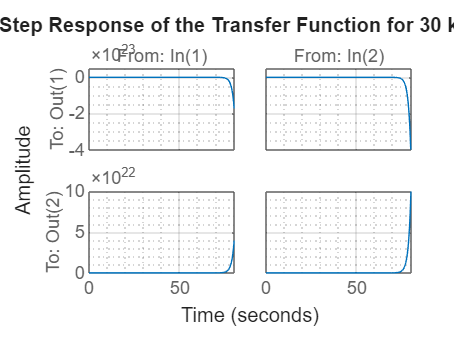

%% Alternatively, you can use step response
figure;
stepplot(FBO_U2_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;


% Convert to transfer function and plot
FBO_U1_30 = tf(sys_U1_30knots);
fprintf('La fonction de transfert du système 30 knots :\n');

La fonction de transfert du système 30 knots :


FBO_U1_30


FBO_U1_30 =
 
  From input 1 to output...
               0.004133 s^2 + 0.01247 s + 0.002306
   1:  ---------------------------------------------------
       s^4 + 1.324 s^3 + 0.5347 s^2 + 0.07236 s + 0.002022
 
              -0.000965 s^2 - 0.000148 s + 3.82e-21
   2:  ---------------------------------------------------
       s^4 + 1.324 s^3 + 0.5347 s^2 + 0.07236 s + 0.002022
 
  From input 2 to output...
               -0.02722 s^2 - 0.08212 s - 0.01519
   1:  ---------------------------------------------------
       s^4 + 1.324 s^3 + 0.5347 s^2 + 0.07236 s + 0.002022
 
             0.006355 s^2 + 0.0009748 s - 2.515e-20
   2:  ---------------------------------------------------
       s^4 + 1.324 s^3 + 0.5347 s^2 + 0.07236 s + 0.002022
 
Continuous-time transfer function.


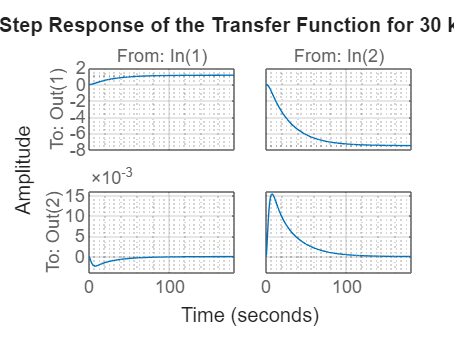

%% Alternatively, you can use step response
figure;
stepplot(FBO_U1_30);
title('Step Response of the Transfer Function for 30 knots');
grid minor;

# **Parti IX : Conclusion**

Ce bureau d'étude nous à permet d'étudier le comportement de systèmes à multivariables. Nous avons tout d'abord axaminer la controlabilité et l'observabilité de notre système. Nous avons également eu l'occasion d'implémenter des méthodes de placement de pôles afin d'imposer une certaine dynamique à notre système, mais également mettre en place des méthodes de découplage, permettant de simplifier le contrôle du système. Ce découplage à pu se faire d'abord à droite en déterminant la forme de la matrice V qui assure un découplage des sorties, mais aussi à gauche par la détermination de notre matrice H.

Enfin, une dernière partie traitée de l'étude de sensibilité des pôles ainsi choisis. Cette étude s'est faite par utilisation de la fonction MATLAB cond.m permettant d'analyser la sensibilité.